# Ground Truth Validation: 

Compare published datasets against code changes.

% Path Setup
% gt : ground truth
% mbo: comparison dataset
clc; 

## Optional: Rename planes

clc;
order = fliplr([1 5:10 2 11:17 3 18:23 4 24:30]);
% rename_planes(mcpath, order);

clc;plane = 1;
v2_path = 'C:/Users/RBO/Documents/data/high_res/v1.4_mc/';
v2_full = sprintf('%s/motion_corrected_plane_1.h5', v2_path);
save_path = fullfile("C:/Users/RBO/Desktop/figs/");
gt = sprintf('C:/Users/RBO/Documents/data/ground_truth/high_res/Fig4a-c_dataset_plane_30.mat');
Ym_v2 = mean(read_plane(v2_path, '/mov', 1, 1:1730),3);
Ym_gt = matfile(gt).Ym;


varnames = 5×2 single matrix
1.0e+03 *

    1.3030    1.3025
    1.0245    1.0157
    1.1899    1.1870
    0.9879    0.9791
    1.1223    1.1184


T = 5×1 table
        varnames    
    ________________

      1303    1302.5
    1024.5    1015.7
    1189.9      1187
    987.86    979.12
    1122.3    1118.4


## Check that both arrays are equal, within a tolerance

% https://stackoverflow.com/questions/38104651/test-if-arrays-are-proportional
% Using isequal() fails with rounding errors
% Test for proportionality with 2% tolerance

C = Ym_v2./Ym_gt; % element-wise
tol = 0.02; % tolerance (5%)
all(all(abs(diff(C))<tol))

ans = logical
   1


C

C = 583×528 single matrix
    1.0003    0.9938    1.0007    0.9990    1.0002    0.9993    1.0008    0.9989    0.9996    0.9986    1.0003    0.9984    1.0008    0.9980    0.9994    0.9983    1.0003    0.9994    1.0014    0.9993    1.0001    0.9980    1.0004    0.9994    0.9991    0.9959    0.9993    0.9990    0.9963    0.9992    0.9982    0.9973    0.9990    0.9994    0.9980    0.9991    0.9989    0.9992    0.9987    0.9999    0.9988    0.9991    0.9971    0.9975    0.9969    0.9966    0.9992    0.9976    0.9993    0.9976
    1.0087    0.9939    1.0038    0.9990    1.0023    0.9992    1.0019    0.9998    1.0006    0.9994    1.0019    0.9998    1.0019    0.9999    1.0005    0.9997    1.0017    1.0004    1.0017    0.9998    1.0018    1.0003    1.0003    1.0003    1.0005    0.9996    1.0016    0.9991    1.0010    1.0000    1.0010    0.9995    1.0002    1.0001    0.9995    1.0015    1.0020    1.0020    1.0010    1.0015    1.0022    1.0018    1.0018    1.0004    0.9996    0.9992    1.0002   

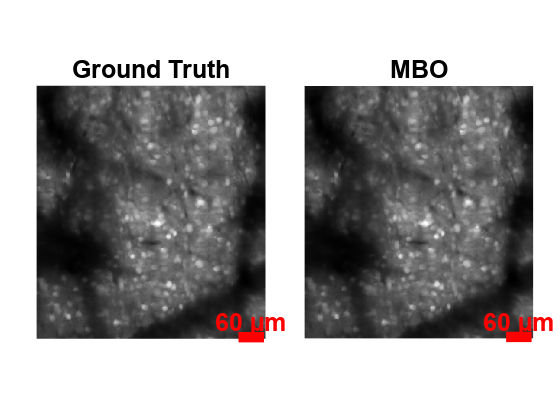

images = {Ym_gt, Ym_v2};
labels = {'Ground Truth', "MBO"};
scales = {60, 60};
make_tiled_figure( ...
    images, ...
    read_h5_metadata(v2, '/mov'), ...
    "titles", labels, ...
    'scales', scales, ...
    'save_name', fullfile(save_path, "GT_COMPARISON.png") ...
    );

## Bi-hemisphere Plane 30 (reordered from plane 1) motion correction validation

% ground truth
data = matfile("C:\Users\RBO\Documents\data\ground_truth\bi_hemisphere\MH184_both_6mm_FOV_150_600um_depth_410mW_9min_no_stimuli_00001_plane_30.mat");
[yind, xind] = get_central_indices(data.Y(:,:,4), 200);
planeToMovie(data.Y(yind, xind, :), "C:\Users\RBO\Documents\data\bi_hemisphere\gt_plane30", 9.6);

data_name = fullfile("C:\Users\RBO\Documents\data\bi_hemisphere\corrected\motion_corrected_plane_1.h5");
h5info(data_name, '/').Datasets
data_new = h5read(data_name, '/mov');

[yind, xind] = get_central_indices(data_new(:,:,4), 200);
planeToMovie(data_new(yind, xind, :), "C:\Users\RBO\Documents\data\bi_hemisphere\new_plane", 9.6);

segment_path = fullfile('C:\Users\RBO\Documents\data\bi_hemisphere\results\');
ym_path = fullfile('C:\Users\RBO\Documents\data\bi_hemisphere\corrected\');

ym_files = dir([ym_path '*_plane_*.h5*']);
segment_files = dir([segment_path '*_plane_*.h5*']);

for i=1:length(ym_files)
    fname = fullfile(ym_files(i).folder, ym_files(i).name);
    sname = fullfile(segment_files(i).folder, segment_files(i).name);
    Ym = mean(h5read(fname, '/mov'),3);
    h5create(sname, '/Ym', size(Ym));
    h5write(sname, '/Ym', Ym);
end
% save_path = fullfile(segment_path, "axial_offset");
